# Non-linear heat conduction in Europa's ice shell

clear, close all, clc

The thermal conductivity of ice is highly temperature dependent and the ice shels of icy ocean worlds experience large temperature differences, from 100 K at the surface to 273 K at the ice ocean interface. 

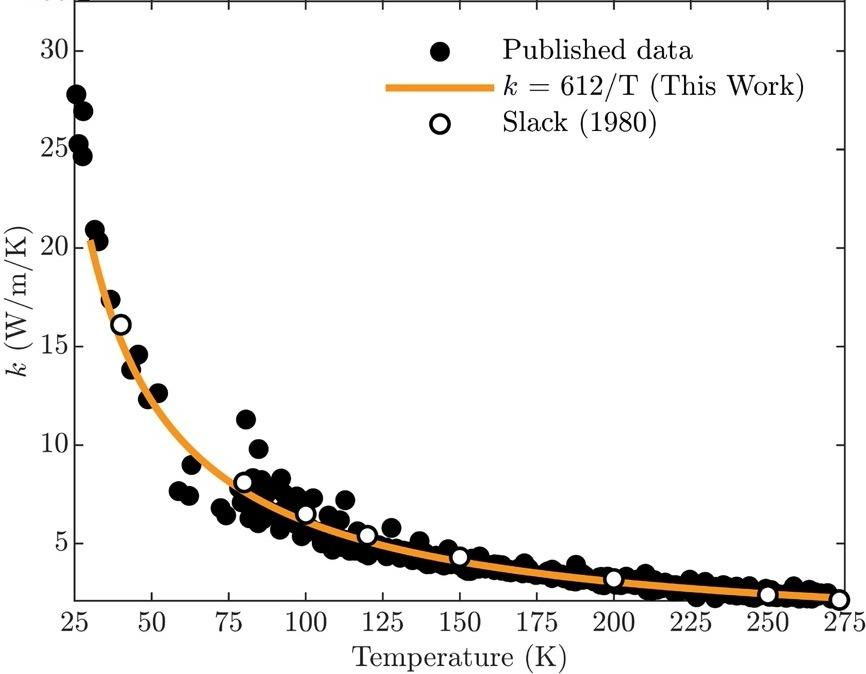

([Carnahan and Wolfenbarger et al. 2021](https://doi.org/10.1016/j.epsl.2021.116886))

kappa0 = 612;
kappa = @(T) kappa0./T;

The steady-state temperature profile of the ice shell is therefore determined by the following non-linear heat conduction problem:

PDE: $-\nabla\cdot\left[\kappa(T)\nabla T\right] = 0$ on $z \in \left[0,\,H\right]$

BCs: $T(0) = T_o$ and $T(H) = T_s$

Here the thichness of the ice shell is $H=30$ km, the ocean and surface temperatures are $T_o=273$ K and $T_s = 100$ K, respectively. The dependence of the thermal conductivity on the temperature is $\kappa = \kappa_0/T$, where $\kappa_0=612$.

In 1D this problem has the following analytic solution:


$$T(z) = T_o \,e^{\ln(T_s/T_o)\,z/H}$$


$q(z) = -\frac{\kappa_0}{H}\ln(T_s/T_o)$= constant.

For the parameters given this leads to an increase of the thermal conductivity from 2.24 at the base to 6.12 W/(m K) at the top (a factor of 2.7).

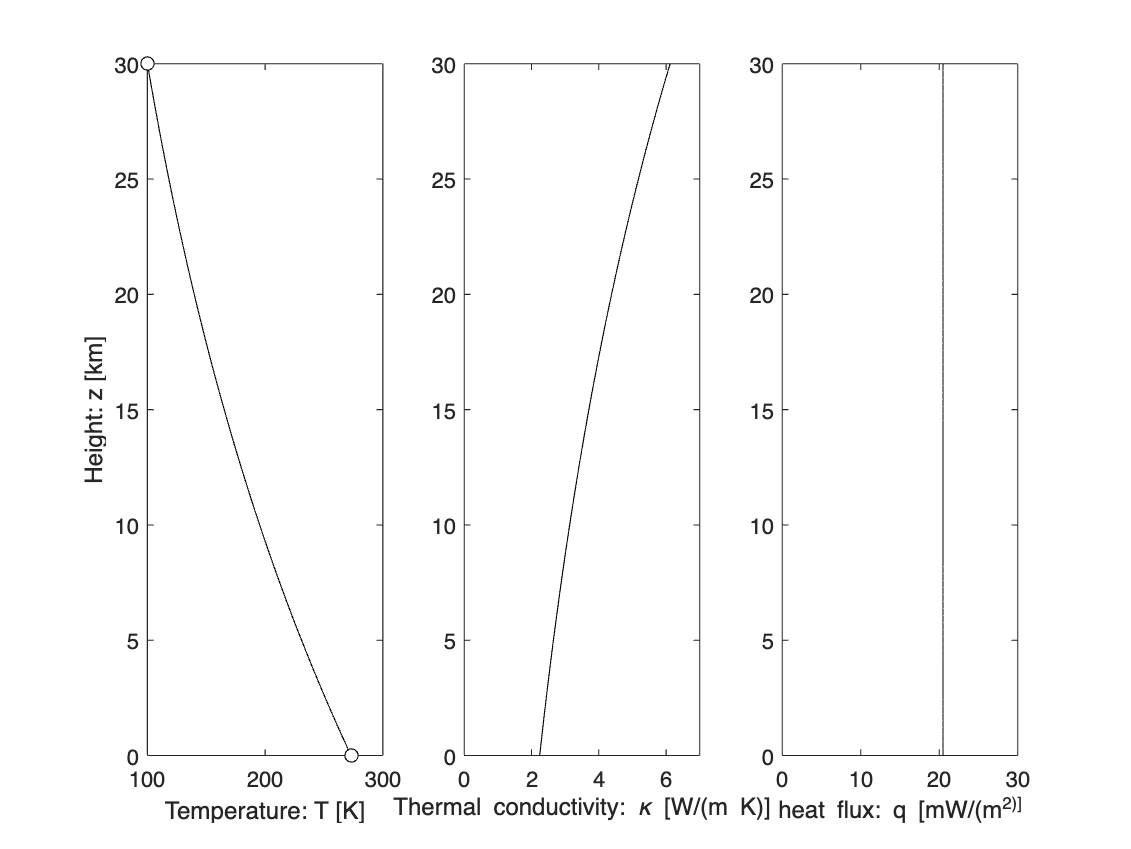

H = 30e3; % [m] ice shell thickness
Ts = 100; % [K] surface temperature
To = 273; % [K] ocean temperature
z_ana = linspace(0,H,1e2);

T_ana = @(z) To*exp(log(Ts/To)*z/H);
q_ana = @(z) -kappa0/H*log(Ts/To)+0*z;

subplot 131
plot(T_ana(z_ana),z_ana/1e3,'k-'), hold on
plot([To Ts],[0 H]/1e3,'ko','MarkerFaceColor','w')
xlabel('Temperature: T [K]')
ylabel('Height: z [km]')

subplot 132
plot(kappa(T_ana(z_ana)),z_ana/1e3,'k-')
xlabel('Thermal conductivity: \kappa [W/(m K)]')
xlim([0 7])

subplot 133
plot(q_ana(T_ana(z_ana))*1e3,z_ana/1e3,'k-'), hold on
xlabel('heat flux: q [mW/(m^2)]')
xlim([0 30])

## Newton-Rasphson with numerical Jacobian

Grid.xim = 0; Grid.xmax = H; Grid.Nx = 2e1;
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
fs = spalloc(Grid.N,1,0);
Kd = @(u) comp_mean(kappa(u),M,1,Grid,1);
res = @(u) -D*Kd(u)*G*u - fs;

BC.dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.g = T_ana(Grid.xc(BC.dof_dir));

[B,N,fn,BC] = build_bnd(BC,Grid,I);

%% Newton iteration
tol = 1e-6;         % convergence tolerance
epsilon = 1e-8;     % perturbation for numerical derivative
nmax = 10;          % maximum number of iterations
nres = 1; ndu = 1;

u = (To+Ts)/2*ones(Grid.N,1);

% BC in NR are added to initial guess -> homogneous during iteration
u(BC.dof_dir) = BC.g; 
BC.g = [0;0];

fprintf('Newton-Raphson iteration\n')

Newton-Raphson iteration


n = 0;
while (nres > tol || ndu > tol) && n < nmax
     n = n+1; 

    % 1) update solution
    Jac = comp_jacobian_steady_heat_flow_num(res,u,Grid,epsilon);
    du = solve_lbvp(Jac,-res(u),B,BC.g,N);
    u = u+du; 
    
    % 2) check for convergence
    nres = norm(N'*res(u)); 
    ndu = norm(du);
    fprintf('it = %d: nres = %3.2e  ndu = %3.2e\n',n,nres,ndu)
end

it = 1: nres = 5.08e-05  ndu = 2.07e+02
it = 2: nres = 3.66e-06  ndu = 2.44e+01
it = 3: nres = 1.94e-08  ndu = 1.21e+00
it = 4: nres = 4.20e-13  ndu = 4.41e-03
it = 5: nres = 7.27e-19  ndu = 7.82e-08


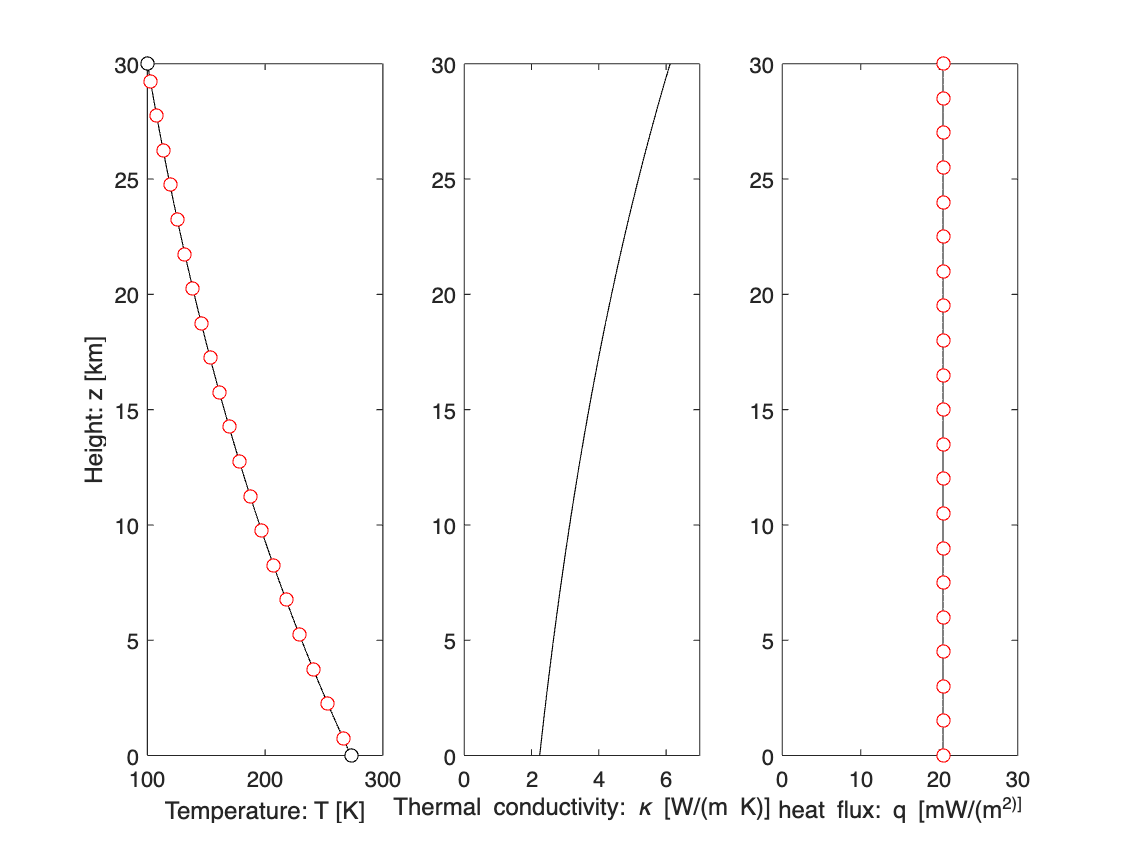


% Compute heat flux
q = comp_flux(D,Kd(u),G,u,fs,Grid,BC);


%% Plot numerical solution
subplot 131
plot(u,Grid.xc/1e3,'ro','MarkerFaceColor','w')

subplot 133
plot(q*1e3,Grid.xf/1e3,'ro','MarkerFaceColor','w')

# Auxillary functions

## Jacobian

function [Jac] = comp_jacobian_steady_heat_flow_num(res,u,Grid,epsilon)
u_perturb=u;
% Pre-allocate storage (important to speed up the for loop)
Jac = spalloc(Grid.N,Grid.N,3*Grid.N);

% %% Computing the Jacobian by finite difference
% % Loop over each unknown and
% % 1) Perturb it
% % 2) Compute the change in residual vector
% % 3) Store the change from unperturbed vector as column of Jacobnian
% % 4) Reset the perturbed value

for i=1:Grid.N
    u_perturb(i)=u(i)+epsilon;
    Jac(:,i)=(res(u_perturb)-res(u))/epsilon;
    u_perturb(i)=u(i);
end
end
